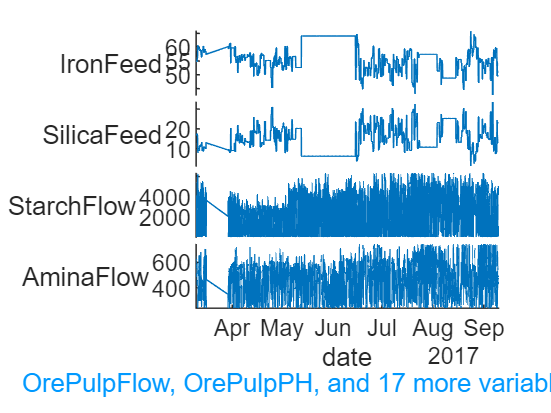

% % inital look to the minin flotation data
% Content (taken from kaggle)
% The first column shows time and date range (from march of 2017 until september of 2017). Some columns were sampled every 20 second. Others were sampled on a hourly base.
% 
% The second and third columns are quality measures of the iron ore pulp right before it is fed into the flotation plant. 
% Column 4 until column 8 are the most important variables that impact in the ore quality in the end of the process. 
% From column 9 until column 22, we can see process data (level and air flow inside the flotation columns, which also impact in ore quality. 
% The last two columns are the final iron ore pulp quality measurement from the lab.
% Target is to predict the last column, which is the % of silica in the iron ore concentrate.
clear all
clc
load("mininProcessData.mat");
origData = MiningProcessFlotationPlantDatabase; % this is to get a bit shorter name for the data
stackedplot(table2timetable(origData))

x24 =    55.2000
   55.2000
   55.2000
   55.2000
   55.2000
   55.2000
   55.2000
   55.2000
   55.2000
   55.2000


x24 =    16.9800
   16.9800
   16.9800
   16.9800
   16.9800
   16.9800
   16.9800
   16.9800
   16.9800
   16.9800


x24 = 	1.0e+03 *

    3.0195
    3.0244
    3.0435
    3.0474
    3.0337
    3.0791
    3.1278
    3.1529
    3.1473
    3.1426


x24 =   557.4340
  563.9650
  568.0540
  568.6650
  558.1670
  564.6970
  566.4670
  558.7770
  556.0300
  565.8570


x24 =   395.7130
  397.3830
  399.6680
  397.9390
  400.2540
  396.5330
  392.9000
  397.0020
  394.3070
  393.1050


x24 =    10.0664
   10.0672
   10.0680
   10.0689
   10.0697
   10.0705
   10.0713
   10.0722
   10.0730
   10.0738


x24 =     1.7400
    1.7400
    1.7400
    1.7400
    1.7400
    1.7400
    1.7400
    1.7400
    1.7400
    1.7400


x24 =   249.2140
  249.7190
  249.7410
  249.9170
  250.2030
  250.7300
  250.3130
  249.8950
  250.1370
  249.6530


x24 =   253.2350
  250.5320
  247.8740
  254.4870
  252.1360
  248.9060
  252.2020
  253.6300
  251.1040
  252.2020


x24 =   250.5760
  250.8620
  250.3130
  250.0490
  249.8950
  249.5210
  249.0820
  249.2580
  248.7740
  248.2030


x24 =   295.0960
  295.0960
  295.0960
  295.0960
  295.0960
  295.0960
  295.0960
  295.0960
  295.0960
  295.0960


x24 =   306.4000
  306.4000
  306.4000
  306.4000
  306.4000
  306.4000
  306.4000
  306.4000
  306.4000
  306.4000


x24 =   250.2250
  250.1370
  251.3450
  250.4220
  249.9830
  250.3560
  250.9500
  249.4560
  248.5770
  248.5110


x24 =   250.8840
  248.9940
  248.0710
  251.1470
  248.9280
  251.8730
  253.4770
  253.3450
  250.8840
  248.1370


x24 =   457.3960
  451.8910
  451.2400
  452.4410
  452.4410
  444.3840
  446.1850
  445.9850
  446.6860
  445.6850


x24 =   432.9620
  429.5600
  468.9270
  458.1650
  452.9000
  443.2690
  444.5710
  461.3410
  478.3850
  478.7790


x24 =   424.9540
  432.9390
  434.6100
  442.8650
  450.5230
  460.4490
  452.3060
  461.6400
  459.1030
  460.6650


x24 =   443.5580
  448.0860
  449.6880
  446.2100
  453.6700
  439.9200
  431.3280
  442.0670
  455.0740
  457.2250


x24 =   502.2550
  496.3630
  484.4110
  471.4110
  462.5980
  451.5880
  443.5480
  441.7300
  439.7980
  453.2360


x24 =   446.3700
  445.9220
  447.8260
  437.6900
  443.6820
  433.5390
  444.5750
  461.7700
  457.7380
  449.8980


x24 =   523.3440
  498.0750
  458.5670
  427.6690
  425.6790
  425.4580
  431.2510
  449.6790
  455.9150
  455.7500


x24 =    66.9100
   66.9100
   66.9100
   66.9100
   66.9100
   66.9100
   66.9100
   66.9100
   66.9100
   66.9100


x24 =     1.3100
    1.3100
    1.3100
    1.3100
    1.3100
    1.3100
    1.3100
    1.3100
    1.3100
    1.3100


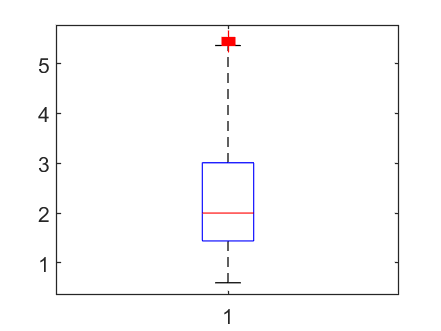


    x24=table2array(MiningProcessFlotationPlantDatabase(:,i))
    boxplot(x24)


clean SilicaConcentrate data

newSilicaConcentrate=MiningProcessFlotationPlantDatabase(37615:end,16:24)

newSilicaConcentrate = 699839×9 table
    FlotationColumn01Level    FlotationColumn02Level    FlotationColumn03Level    FlotationColumn04Level    FlotationColumn05Level    FlotationColumn06Level    FlotationColumn07Level    IronConcentrate    SilicaConcentrate
    ______________________    ______________________    ______________________    ______________________    ______________________    ______________________    ______________________    _______________    _________________

            807.18                    799.42                    799.61                    461.45                    476.49                    421.79                    449.98                 64.03             

timetable=MiningProcessFlotationPlantDatabase(37615:end,1)

timetable = 699839×1 table
           date        
    ___________________

    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00
    2017-04-01 00:00:00


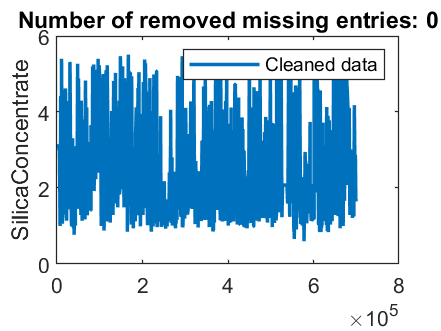

% Remove missing data
[newTable,missingIndices] = rmmissing(newSilicaConcentrate);

% Display results
clf
plot(find(~missingIndices),newTable.SilicaConcentrate,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("SilicaConcentrate")

clear x y

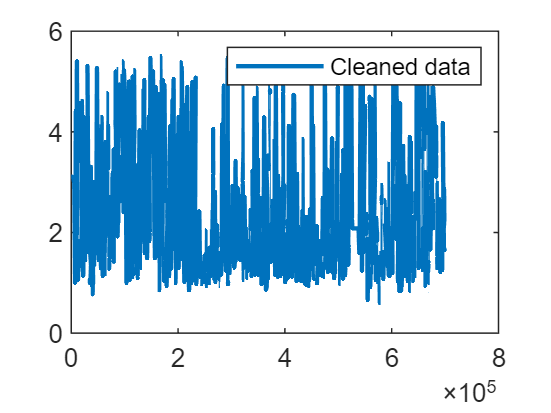

% Remove outliers
[cleanedData,outlierIndices] = ...
    rmoutliers(newSilicaConcentrate.SilicaConcentrate,"movmedian",1100);

% Display results
clf
plot(find(~outlierIndices),cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

legend

clean   Flotation Column Level 1-7

FlotationColumnLevel1_7=MiningProcessFlotationPlantDatabase(37615:end,16:22)

FlotationColumnLevel1_7 = 699839×7 table
    FlotationColumn01Level    FlotationColumn02Level    FlotationColumn03Level    FlotationColumn04Level    FlotationColumn05Level    FlotationColumn06Level    FlotationColumn07Level
    ______________________    ______________________    ______________________    ______________________    ______________________    ______________________    ______________________

            807.18                    799.42                    799.61                    461.45                    476.49                    421.79                    449.98        
               810                    791.18                    800.32                    471.73                    472.11                    460.95                    453

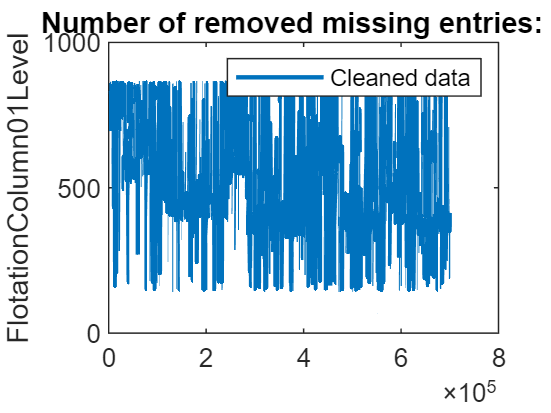

% Remove missing data
[newTable2,missingIndices2] = rmmissing(FlotationColumnLevel1_7);

% Display results
clf
plot(find(~missingIndices2),newTable2.FlotationColumn01Level,...
    "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Cleaned data")
hold on

indicesForPlot = ismissing(FlotationColumnLevel1_7.FlotationColumn01Level);

% Plot data in rows where other variables contain missing entries
mask = missingIndices2 & ~indicesForPlot;
plot(find(mask),FlotationColumnLevel1_7.FlotationColumn01Level(mask),"x",...
    "Color",[64 64 64]/255,"DisplayName","Removed by other variables")

% Plot removed missing entries
x2 = repelem(find(indicesForPlot),3);
y2 = repmat([ylim(gca) missing]',nnz(indicesForPlot),1);
plot(x2,y2,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(indicesForPlot))

hold off
legend
ylabel("FlotationColumn01Level")

clear indicesForPlot mask x2 y2

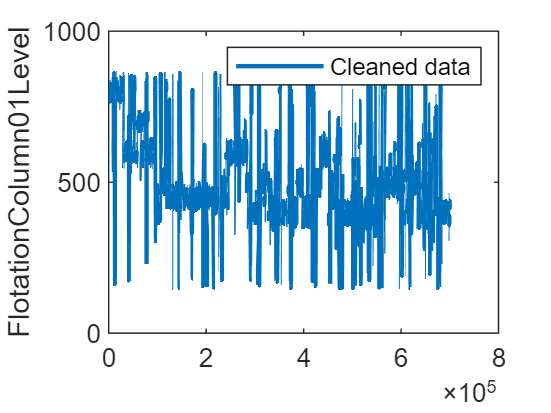

% Remove outliers
[newTable3,outlierIndices2] = rmoutliers(FlotationColumnLevel1_7,"movmedian",380);

% Display results
clf
plot(find(~outlierIndices2),newTable3.FlotationColumn01Level,...
    "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Cleaned data")

legend
ylabel("FlotationColumn01Level")